% 根据病人的年龄和身高预测血压最高值
% 采用kNN解决回归问题
% 具体使用knnsearch和mean

## 导入医院数据集

load hospital;

disp(hospital)  % 展示一下hospital的内容

               LastName              Sex       Age    Weight    Smoker    BloodPressure      Trials             
    YPL-320    {'SMITH'     }        Male      38     176       true      124          93    {[         18]}    
    GLI-532    {'JOHNSON'   }        Male      43     163       false     109          77    {[   11 13 22]}    
    PNI-258    {'WILLIAMS'  }        Female    38     131       false     125          83    {1×0 double   }    
    MIJ-579    {'JONES'     }        Female    40     133       false     117          75    {[       6 12]}    
    XLK-030    {'BROWN'     }        Female    49     119       false     122          80    {[      14 23]}    
    TFP-518    {'DAVIS'     }        Female    46     142       false     121          70    {[         19]}    
    LPD-746    {'MILLER'    }        Female    33     142       true      130          88    {[         13]}    
    ATA-945    {'WILSON'    }        Male      40     180       false     115          82    {1×

X = [hospital.Age hospital.Weight];
Y= hospital.BloodPressure(:,1);

## Case 1 对5个病人进行预测，没有高血压的真值

X_new = [20 162; 30 169; 40 168; 50 170; 60 171];   % 5个新病人

% 默认的knnsearch
Idx = knnsearch(X,X_new);
% Find the patients in X closest in age and weight to those in Y.
X(Idx,:)

ans =     25   171
    25   171
    39   164
    49   170
    50   172


Y_pre1=mean(Y(Idx),2)  %最近邻的Y的平均值

Y_pre1 =    128
   128
   128
   129
   125



% 改变knnsearch参数
Idx2 = knnsearch(X,X_new,'K',2,'Distance','minkowski','P',5);
X(Idx2(:,1),:)  % 第1个最近邻的X

ans =     25   171
    25   171
    39   164
    49   170
    50   172


X(Idx2(:,2),:)  % 第2个最近邻的X

ans =     25   174
    25   174
    44   169
    50   172
    49   170


Y_pre2=mean(Y(Idx2),2)  %最近邻的Y的平均值

Y_pre2 =   127.5000
  127.5000
  130.0000
  127.0000
  127.0000


% 比较一下结果
[Y_pre1 Y_pre2]

ans =   128.0000  127.5000
  128.0000  127.5000
  128.0000  130.0000
  129.0000  127.0000
  125.0000  127.0000


## Case 2 对所有数据集进行预测

采用knnsearch和自取平均值方法

kk=2

kk = 2

Idx3 = knnsearch(X,X,'K',kk);
Y_pre3=mean(Y(Idx3),2)

Y_pre3 =   122.0000
  118.5000
  119.0000
  118.5000
  125.0000
  124.5000
  126.5000
  119.5000
  117.0000
  115.5000


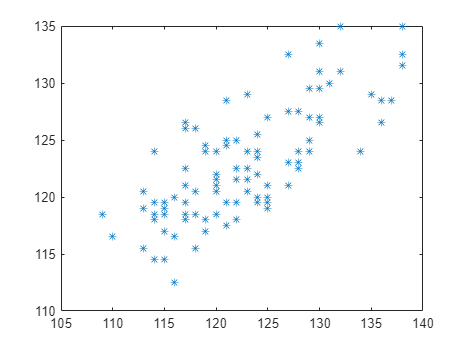


% 比较结果
figure;
plot(Y,Y_pre3,'*');